# Load Scenario Data

clearvars
close all
clc

addpath('C:\dynare\6.1\matlab')
% Define scenario metadata
casScenarios = {'Baseline', 'NZ'};%, 'PDP8_subsidies', 'PDP8_lowrG'};%, 'NZ_subsidies'}%, 'NZ_constEE', 'Finance_RG'};
caslegendentries = {'PDP8', 'Net Zero'};%, 'PDP8 subsidies', 'PDP8 low interest rate'};%, 'NZ subsidies'};%, 'Net Zero', 'NZ_constEE', 'Finance Government'};
casLinetypes = {'-', '+-'};%, '-.', '.', '+'};

% Load scenario CSV data
dsall = struct();
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    filename = ['ExcelFiles/Output/' sScen '.csv'];
    dsall.(sScen) = readtable(filename);
end

Tplot = 30; % Years to plot
ilw = 2

ilw = 2

## Emissions Plot

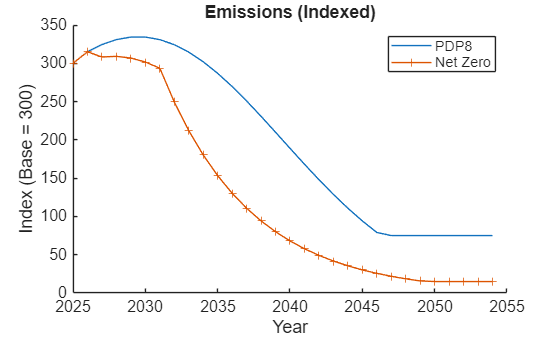

figure('Name', 'Emissions');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.E_1(1:Tplot) ./ ds.E_1(1) * 300, sline);
end
title('Emissions (Indexed)')
legend(caslegendentries)
xlabel('Year')
ylabel('Index (Base = 300)')
hold off

## Energy Productivity

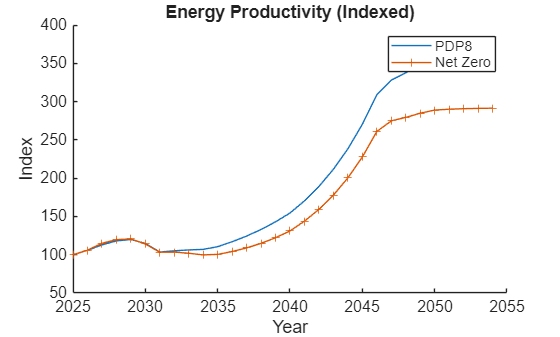

figure('Name', 'Energy productivity');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    productivity = ds.Y_1 ./ (ds.Q_D_2_1 + ds.Q_D_3_1);
    plot(ds.Year(1:Tplot), productivity(1:Tplot) / productivity(1) * 100, sline);
end
title('Energy Productivity (Indexed)')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

## Cap and Trade Revenues

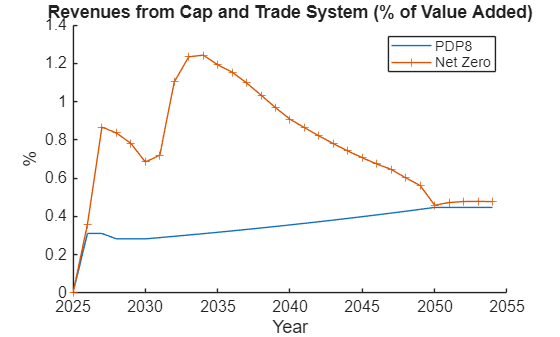

figure('Name', 'Cap and Trade Revenues');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    revenues = ds.PE_1 .* ds.E_1 ./ (ds.Q_1 - ds.Q_I_1) * 100;
    plot(ds.Year(1:Tplot), revenues(1:Tplot), sline);
end
title('Revenues from Cap and Trade System (% of Value Added)')
legend(caslegendentries)
xlabel('Year')
ylabel('%')
hold off

## GDP Growth

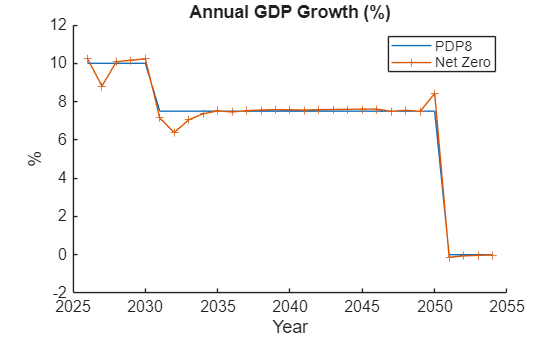

figure('Name', 'GDP Growth');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    growth = (ds.Y_1(2:Tplot) ./ ds.Y_1(1:Tplot-1) - 1) * 100;
    plot(ds.Year(2:Tplot), growth, sline);
end
title('Annual GDP Growth (%)')
legend(caslegendentries)
xlabel('Year')
ylabel('%')
hold off

## Renewable Energy Share (RES)

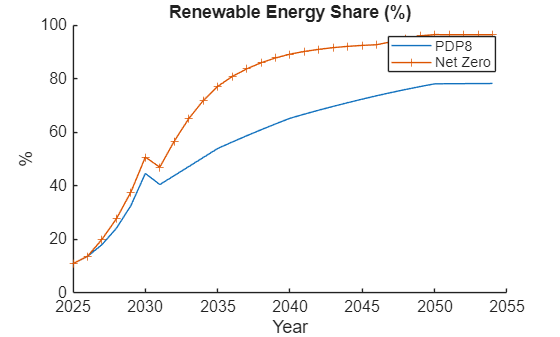

figure('Name', 'Renewable Energy Share');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    res_share = (ds.Q_D_3_1+ds.Q_PV_1) ./ (ds.Q_D_2_1 + ds.Q_D_3_1+ds.Q_PV_1) .* 100;
    plot(ds.Year(1:Tplot), res_share(1:Tplot), sline);
end
title('Renewable Energy Share (%)')
legend(caslegendentries)
xlabel('Year')
ylabel('%')
hold off

## Emission Intensity

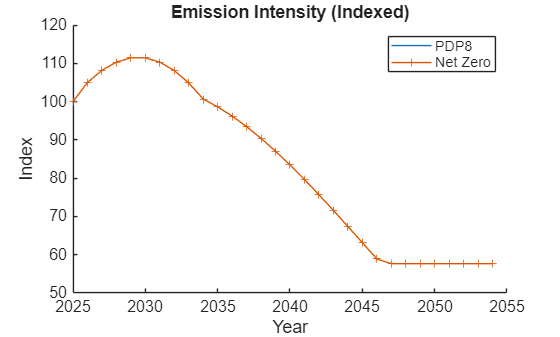

figure('Name', 'Emission Intensity');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.kappaE_2_1(1:Tplot) / ds.kappaE_2_1(1) * 100, sline);
end
title('Emission Intensity (Indexed)')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

## Emission Price

figure('Name', 'Emission Price');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.PE_1(1:Tplot), sline);
end
title('Emission Price')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

## Return on Rented Capital (Households)


ssubsec = '3';
if ssubsec == '1'
    ssectorname = 'Agriculture';
elseif ssubsec == '2'
    ssectorname = 'Fossil';
elseif ssubsec == '3'
    ssectorname = 'Renewables';
elseif ssubsec == '4'
    ssectorname = 'Manufacturing';
elseif ssubsec == '5'
    ssectorname = 'Services';
end
icofig = 0;
icofig = icofig + 1;
strfig(icofig).Name = [ssectorname ' Return on Rented Capital (Households)'];
strfig(icofig).Symbol = ['r_F_' ssubsec '_1'];
icofig = icofig + 1;
strfig(icofig).Name = [ssectorname ' Wages'];
strfig(icofig).Symbol = ['W_' ssubsec '_1'];
icofig = icofig + 1;
strfig(icofig).Name = [ssectorname ' Labour'];
strfig(icofig).Symbol = ['N_' ssubsec '_1'];
icofig = icofig + 1;
strfig(icofig).Name =  [ssectorname ' Capital'];
strfig(icofig).Symbol = ['K_' ssubsec '_1'];
icofig = icofig + 1;
strfig(icofig).Name = [ssectorname ' Intermediate Prices'];
strfig(icofig).Symbol = ['P_I_' ssubsec '_1'];
icofig = icofig + 1;
strfig(icofig).Name = [ssectorname ' Price'];
strfig(icofig).Symbol = ['P_Q_' ssubsec '_1'];
icofig = icofig + 1;
strfig(icofig).Name = [ssectorname ' Productivity'];
strfig(icofig).Symbol = ['A_' ssubsec '_1'];
icofig = icofig + 1;
strfig(icofig).Name = 'Energy Productivity';
strfig(icofig).Symbol = 'EE_1';
icofig = icofig + 1;
strfig(icofig).Name = 'Emission Price';
strfig(icofig).Symbol = 'PE_1';
for icofig = 1:size(strfig,2)
    sname = strfig(icofig).Name;
    ssymb = strfig(icofig).Symbol;
    figure('Name', sname);
    hold on
    for iscen = 1:length(casScenarios)
        sScen = casScenarios{iscen};
        ds = dsall.(sScen);
        sline = casLinetypes{iscen};
        % plot(ds.Year(2:Tplot), (1+ds.r_H_' ssubsec '_1(2:Tplot)).*(1-ds.tauKH_' ssubsec '_1(2:Tplot)).*ds.P_' ssubsec '_1(2:Tplot)./ds.P_' ssubsec '_1(1:Tplot-1)-1, sline);
        plot(ds.Year(1:Tplot), ds.(ssymb)(1:Tplot), sline);
        
    end
    title(sname)
    legend(caslegendentries)
    xlabel('Year')
    ylabel('Index')
    hold off
end


## Renewable Capital Stock

figure('Name', 'Renewable Capital Stock');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.K_3_1(1:Tplot), sline);
end
title('Renewable Capital Stock')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off
figure('Name', 'Renewable Labour');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.N_3_1(1:Tplot), sline);
end
title('Renewable Labor')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

figure('Name', 'Renewable Price');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.P_3_1(1:Tplot), sline);
end
title('Renewable Price')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

## Energy Efficiency

figure('Name', 'Energy Efficiency');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.EE_1(1:Tplot) / ds.EE_1(1) * 100, sline);
end
title('Energy Efficiency (Indexed)')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

## Emission Price

figure('Name', 'Emission Price');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.PE_1(1:Tplot) / ds.PE_1(1), sline);
end
title('Emission Price (Relative to Base Year)')
legend(caslegendentries)
xlabel('Year')
ylabel('Relative Price')
hold off

## Fossil Energy Production


figure('Name','Fossil Energy Production'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), ds.Q_2_1(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Fossil Energy Production'); legend(caslegendentries); hold off

%% 19. Renewable Energy Production
figure('Name','Renewable Energy Production'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), ds.Q_3_1(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Renewable Energy Production'); legend(caslegendentries); hold off

%% 20. Fossil Energy Price (Value Added)
figure('Name','Fossil Energy Price – VA'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), ds.P_2_1(1:Tplot) * 100, casLinetypes{iscen});
end
xlabel('Year'); ylabel('Price Index'); title('Relative Price of Fossil Energy'); legend(caslegendentries); hold off

%% 21. Sectoral Shares in Value Added -------------------------------------
% Agriculture
figure('Name','VA Share – Agriculture'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareAg = ds.P_1_1 .* ds.Y_1_1 ./ ds.Y_1 * 100;
    plot(ds.Year(1:Tplot), shareAg(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Agriculture Share in VA'); legend(caslegendentries); hold off

% Manufacturing
figure('Name','VA Share – Manufacturing'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareMan = ds.P_4_1 .* ds.Y_4_1 ./ ds.Y_1 * 100;
     plot(ds.Year(1:Tplot), shareMan(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Manufacturing Share in VA'); legend(caslegendentries); hold off


% Government Expenditure
figure('Name','Government Expenditure'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareMan = ds.G./ds.Y.*100;
     plot(ds.Year(1:Tplot), shareMan(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Government Expenditure'); legend(caslegendentries); hold off

% Government Expenditure
figure('Name','Investment into Fossil'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareMan = ds.I_2_1;
     plot(ds.Year(1:Tplot), shareMan(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Investment into Fossil'); legend(caslegendentries); hold off

figure('Name','Investment into Renewables'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareMan = ds.P_INV_3_1.*ds.I_3_1./ds.Y;
     plot(ds.Year(1:Tplot), shareMan(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Investment into Renewables'); legend(caslegendentries); hold off

## Conclusion

disp("All scenario plots generated.")
